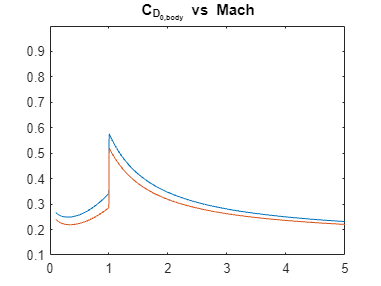

clear; close; clc;



numPoints = 1000;

l = convlength(12,"ft","m");

bodyFineness = 18;
noseFineness = 2.4;

d = l / bodyFineness;
l_N = d * noseFineness;

d_noseTip = 0;
d_bt = d;
A_e = convlength(convlength(11.22,"in","m"),"in","m"); % two linear conversion is equvalent to an area conversion


h = convlength(20e3,"ft","m"); % alt

M = linspace(.1,5,numPoints); %should use linspace
C_D_0_body = zeros(numPoints,2);

isCoasting = true;

for i = 1:numPoints
    [~, a, ~, rho] = atmosisa(h);
    v = M(i) * a; % velocity from mach and speeed of sound
    q = 1/2 * rho * v^2;
    C_D_0_body(i,1) = dragCoeff_zeroLift_body(M(i), q, l, l_N, d, d_noseTip, d_bt, A_e, true);
    C_D_0_body(i,2) = dragCoeff_zeroLift_body(M(i), q, l, l_N, d, d_noseTip, d_bt, A_e, false);
end

plot(M, C_D_0_body); ylim([.1, 1]); title("C_{D_{0,body}} vs Mach")

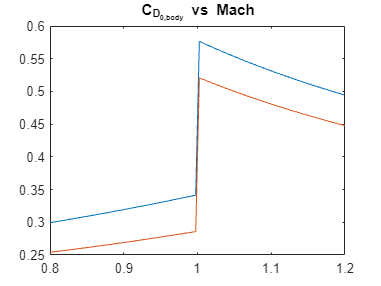

plot(M, C_D_0_body);  xlim([.8,1.2]); title("C_{D_{0,body}} vs Mach")

## boat tail



l = 10.5

l = 10.5000

l_N = 3

l_N = 3

d = .2/3.2 *l

d = 0.6563

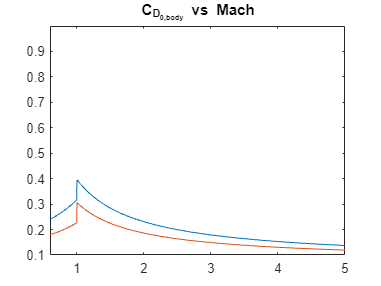

d_noseTip = 0;
d_bt = d;

for i = 1:numPoints
    [~, a, ~, rho] = atmosisa(h);
    v = M(i) * a; % velocity from mach and speeed of sound
    q = 1/2 * rho * v^2;
    C_D_0_body(i,1) = dragCoeff_zeroLift_body(M(i), q, l, l_N, d, d_noseTip, d, A_e, true);
    C_D_0_body(i,2) = dragCoeff_zeroLift_body(M(i), q, l, l_N, d, d_noseTip, d*.8, A_e, true);
end


plot(M, C_D_0_body); ylim([.1, 1]); xlim([.6,5]); title("C_{D_{0,body}} vs Mach")

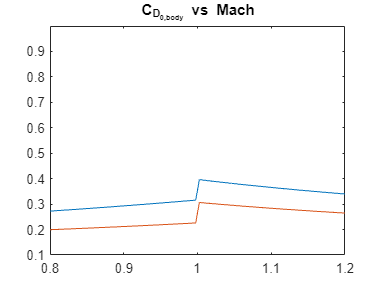

plot(M, C_D_0_body); ylim([.1, 1]); xlim([.8,1.2]); title("C_{D_{0,body}} vs Mach")